# **Testing** **- Acquadro Patrizio (502311), Uttini Lorenzo (502183)**

## **Applying Gamma Correction, Classification, and Entropy Evaluation to New Images**

**Description: **This script processes all images in the 'test' folder, applies gamma correction, classifies the images using a pre-trained SVM model, and evaluates the entropy of the gamma-corrected images. The script ensures the output folder exists, reads and preprocesses each image, applies gamma correction, saves the corrected images, classifies them, and finally evaluates their entropy to determine the quality of the gamma correction.

**Process:**

- **Importing Test Images: **The script starts by importing all images from the 'test' folder. If no images are found, an error message is displayed.

- **Ensuring the Output Folder Exists: **The script specifies the output folder for corrected images and ensures it exists. If the folder does not exist, it is created.

- **Applying Gamma Correction: **Each image in the test folder is read, converted to the YCbCr color space, and gamma correction is applied. The corrected images are saved to the output folder.

- **Classification and Entropy Evaluation:**The script loads the pre-trained SVM model and initializes variables for entropy evaluation. For each corrected image, features are extracted, the class is predicted, and the entropy is calculated. The results are compared to the predefined acceptable entropy range.

## **Import and Preprocess the Test Images**

% Import all images from the 'test' folder
test_image_path = './test';
test_image_files = dir(fullfile(test_image_path, '*.jpg'));
if isempty(test_image_files)
    error('No image files found in the test folder.');
end
test_image_names = {test_image_files.name}';
test_image_fullpaths = cellfun(@(s) fullfile(test_image_path, s), test_image_names, 'UniformOutput', false);

% Parameters for gamma correction
output_folder = fullfile(pwd, 'corrected_images_test'); % Output folder in the current working directory

% Ensure the output folder exists or create it
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
    fprintf('Created output folder: %s\n', output_folder);
end

% Loop through each image in the test folder
for idx = 1:length(test_image_fullpaths)
    % Read and convert the image to YCbCr
    image = imread(test_image_fullpaths{idx});
    image_ycbcr = im2double(rgb2ycbcr(image));

    % Apply gamma correction and save the corrected image using the given function
    save_corrected_images({image_ycbcr}, {test_image_names{idx}}, 1, output_folder, 0.47, 0.039);
end

% Store in two variables the images names and the relative paths
corrected_image_files = dir(fullfile(output_folder, '*.jpg'));
corrected_image_names = {corrected_image_files.name}';
corrected_image_fullpaths = cellfun(@(s) fullfile(output_folder, s), corrected_image_names, 'UniformOutput', false);

% Load the pre-trained SVM model
load('trainedSVM.mat', 'trainedSVM', 'validationAccuracy');

## **Process, Classify and Compute Entropy for each Image**

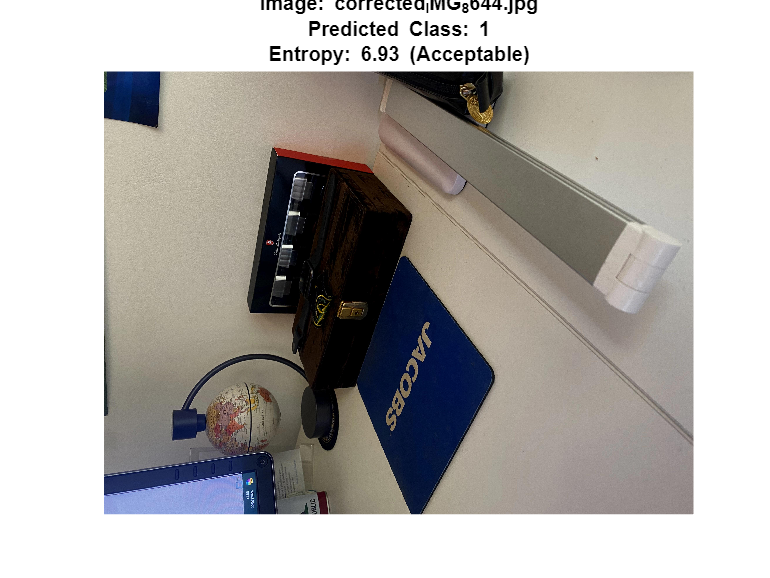

% Initialize variables for entropy evaluation
target_mean_entropy = 7.343380;
target_variance_entropy = 0.065137;
entropy_range = [target_mean_entropy - 2 * sqrt(target_variance_entropy), ...
                 target_mean_entropy + 2 * sqrt(target_variance_entropy)];
num_acceptable = 0;
num_unacceptable = 0;

% Initialize variables for storing results
predicted_classes = zeros(1, length(corrected_image_fullpaths));
entropy_values = zeros(1, length(corrected_image_fullpaths));
acceptability = strings(1, length(corrected_image_fullpaths));

% Loop through each corrected image to store results
for i = 1:length(corrected_image_fullpaths)
    % Extract features from the gamma-corrected image
    features_gamma = extract_feat({corrected_image_fullpaths{i}}, @extract_features_gamma);

    % Predict the class of the corrected image
    predictions_gamma = trainedSVM.predictFcn(features_gamma);
    predicted_classes(i) = predictions_gamma;

    % Evaluate the entropy of the corrected image
    corrected_img = imread(corrected_image_fullpaths{i});
    corrected_img_ycbcr = rgb2ycbcr(corrected_img);
    corrected_img_y = corrected_img_ycbcr(:,:,1);
    entropy_values(i) = calculate_entropy(corrected_img_y); % Use the existing function
    
    % Determine if entropy is acceptable
    if entropy_values(i) >= entropy_range(1) && entropy_values(i) <= entropy_range(2)
        acceptability(i) = "Acceptable";
    else
        acceptability(i) = "Unacceptable";
    end

    % Display the results for each image
    figure;
    imshow(corrected_img, 'InitialMagnification', 'fit');
    title(sprintf('Image: %s\nPredicted Class: %d\nEntropy: %.2f (%s)', corrected_image_names{i}, predictions_gamma, entropy_values(i), acceptability(i)));
end

## **Summary of Results**

### **Classification - General Results**

num_class_1 = sum(predicted_classes == 1);
num_other_classes = length(predicted_classes) - num_class_1;
num_acceptable = sum(acceptability == "Acceptable");
num_unacceptable = sum(acceptability == "Unacceptable");
fprintf('General Classification Results:');

General Classification Results:

fprintf('Number of images predicted as class 1: %d\n', num_class_1);

Number of images predicted as class 1: 1


fprintf('Number of images predicted as other classes: %d\n', num_other_classes);

Number of images predicted as other classes: 0


### **Entropy - General Results**

if num_other_classes > 0
    fprintf('Images predicted as other classes:\n');
    for i = 1:length(predicted_classes)
        if predicted_classes(i) ~= 1
            fprintf('Image: %s, Predicted Class: %d\n', corrected_image_names{i}, predicted_classes(i));
        end
    end
end

% Display the entropy results
fprintf('General Entropy Results:\n');

General Entropy Results:


fprintf('Number of acceptable images: %d\n', num_acceptable);

Number of acceptable images: 1


fprintf('Number of unacceptable images: %d\n', num_unacceptable);

Number of unacceptable images: 0
